% PROBLEM 3

% Clear workspace
close all
clear
clc

% Define the system matrices
Ap = [0 0 1 0 0 0 0 0;
      1.5 -1.5 0 0.0057 1.5 0 0 0;
      -12 12 -0.6 -0.0344 -12 0 0 0;
      -0.825 0.29 0 -0.014 -0.29 0 0 0;
      0 0 0 0 -0.73 2.82940625 0 0;
      0 0 0 0 0 -1.25 0 0;
      0 0 0 0 0 0 -1000 0;
      0 0 0 0 0 0 0 -1000];
Bp = [0 0;
      0.16 0.8;
      -19 -3;
      -0.0115 -0.0087;
      0 0;
      0 0;
      0 0;
      0 0];
Dp = [0 0 0;
      0 0 0;
      0 0 0;
      0 0 0;
      0.1149 0 0;
      4 0 0;
      0 1024 0
      0 0 1024];
Cp = [1 0 0 0 0 0 0 0;
      0 1 0 0 0 0 0 0;
      0 0 0 0 0 0 0 0;
      0 0 0 0 0 0 0 0];
By = [0 0;
      0 0;
      0.01 0;
      0 0.01];
Dy = [0 0 0;
      0 0 0;
      0 0 0;
      0 0 0];
Mp = [1 0 0 0 0 0 -139.020647321 0
      0 1 0 0 0 0 0 -139.020647321];
Dz = [0 142.857142857 0
      0 0 142.857142857];

% Lumped system matrices
A = Ap;
B = [Dp Bp];
C = [Cp; Mp];
D = [Dy By; Dz zeros(size(Dz,1), size(By,2))];

% State-space system
Sol = ss(A, B, C, D)

Sol =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1        0        0        1        0        0        0        0        0
   x2      1.5     -1.5        0   0.0057      1.5        0        0        0
   x3      -12       12     -0.6  -0.0344      -12        0        0        0
   x4   -0.825     0.29        0   -0.014    -0.29        0        0        0
   x5        0        0        0        0    -0.73    2.829        0        0
   x6        0        0        0        0        0    -1.25        0        0
   x7        0        0        0        0        0        0    -1000        0
   x8        0        0        0        0        0        0        0    -1000
 
  B = 
            u1       u2       u3       u4       u5
   x1        0        0        0        0        0
   x2        0        0        0     0.16      0.8
   x3        0        0        0      -19       -3
   x4        0        0        0  -0.0115  -0.0087
   x5   0.1149     

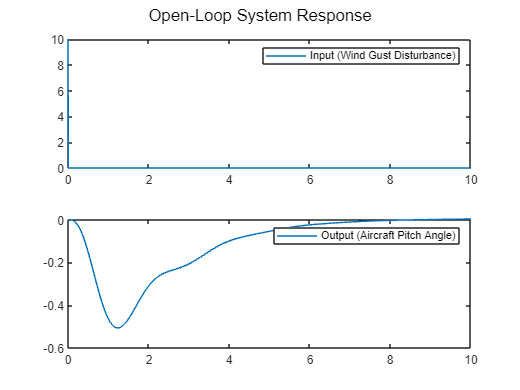


% Define the lumped (disturbance + control) input
t = 0:0.01:10;
w_amplitude = [10; 0; 0];
w_duration = 0.01;
w_impulse = w_amplitude * (t >= 0 & t < w_duration);
u = zeros(size(Bp,2), size(w_impulse,2));
w = [w_impulse; u];

% Simulate the open-loop system response
[y_ol, t_out, x_ol] = lsim(Sol, w', t);

% Plot the results
figure;
sgtitle('Open-Loop System Response');
subplot(2, 1, 1);
plot(t, w(1, :));
legend('Input (Wind Gust Disturbance)');
subplot(2, 1, 2);
plot(t, y_ol(:, 1));
legend('Output (Aircraft Pitch Angle)');


% H∞ controller design
S = ltisys(A, B, C, D);
nz = size(Mp, 1);
nu = size(Bp, 2);
r = [nz nu];
[gopt, G] = hinflmi(S, r)


 Minimization of gamma:

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3                3650.305369
     4                 679.874263
     5                 415.718365
     6                 196.917091
     7                 124.993308
     8                 124.993308
     9                  39.263120
    10                  32.197975
    11                  21.790789
    12                  21.790789
    13                   4.993262
    14                   4.993262
    15                   2.508027
    16                   1.610124
    17                   1.610124
    18                   1.224387
    19                   1.224387
    20                   1.224387
    21                   1.003425
    22                   1.003425
    23                   1.003425
    24                   0.941879
    25                   0.941879
    26                   0.941879
    27                   0.9

gopt = 0.8823

G =    77.0684 -206.4493  -45.4703  -89.5611  -35.5194  -12.4998  106.3172   -2.3242    3.8637    7.0000
 -220.1100  183.7132    2.3812  116.5260   57.5111    1.5305 -226.7402    4.7605   -1.7312         0
  397.2066 -510.2170  -63.3345 -269.2750 -121.1621  -18.7382  432.1665   -5.0789   -3.3582         0
    5.7829   -3.5433    1.5761   -4.9621    1.2446    0.7772    7.5619    1.3169    3.6942         0
  293.4949 -341.9114  -33.2695 -188.0955  -88.9407  -10.9885  313.4063   -1.8555    1.3533         0
   -7.7820    8.1529    0.3504    4.6494    2.2216    0.1100   -8.8267   -0.2847   -0.0942         0
 -263.0885  307.1698   29.7766  169.0752   79.4155    9.7083 -282.4749    0.6617   -0.6630         0
  -60.3310  101.1714   16.6276   48.7081   21.1076    4.7857  -70.3890    0.5497   -0.2233         0
 -102.4696  -63.6786  -48.4705    1.8408   11.4945  -12.2981  -80.1751    0.1321   -0.0537         0
         0         0         0         0         0         0         0         0       


% H∞ controller matrices
disp('H∞ controller:')

H∞ controller:


[Ac, Bc, Cc, Dc] = ltiss(G)

Ac =    77.0684 -206.4493  -45.4703  -89.5611  -35.5194  -12.4998  106.3172
 -220.1100  183.7132    2.3812  116.5260   57.5111    1.5305 -226.7402
  397.2066 -510.2170  -63.3345 -269.2750 -121.1621  -18.7382  432.1665
    5.7829   -3.5433    1.5761   -4.9621    1.2446    0.7772    7.5619
  293.4949 -341.9114  -33.2695 -188.0955  -88.9407  -10.9885  313.4063
   -7.7820    8.1529    0.3504    4.6494    2.2216    0.1100   -8.8267
 -263.0885  307.1698   29.7766  169.0752   79.4155    9.7083 -282.4749


Bc =    -2.3242    3.8637
    4.7605   -1.7312
   -5.0789   -3.3582
    1.3169    3.6942
   -1.8555    1.3533
   -0.2847   -0.0942
    0.6617   -0.6630


Cc =   -60.3310  101.1714   16.6276   48.7081   21.1076    4.7857  -70.3890
 -102.4696  -63.6786  -48.4705    1.8408   11.4945  -12.2981  -80.1751


Dc =     0.5497   -0.2233
    0.1321   -0.0537



% Closed-loop system matrices
disp('Closed-loop system:')

Closed-loop system:


Acl = [Ap+Bp*Dc*Mp, Bp*Cc; Bc*Mp, Ac]

Acl = 1.0e+03 *

         0         0    0.0010         0         0         0         0         0         0         0         0         0         0         0         0
    0.0017   -0.0016         0    0.0000    0.0015         0   -0.0269    0.0109   -0.0916   -0.0348   -0.0361    0.0093    0.0126   -0.0091   -0.0754
   -0.0228    0.0164   -0.0006   -0.0000   -0.0120         0    1.5070   -0.6121    1.4537   -1.7312   -0.1705   -0.9310   -0.4355   -0.0540    1.5779
   -0.0008    0.0003         0   -0.0000   -0.0003         0    0.0010   -0.0004    0.0016   -0.0006    0.0002   -0.0006   -0.0003    0.0001    0.0015
         0         0         0         0   -0.0007    0.0028         0         0         0         0         0         0         0         0         0
         0         0         0         0         0   -0.0013         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -1.0000       

Bcl = [Dp+Bp*Dc*Dz; Bc*Dz]

Bcl = 1.0e+03 *

         0         0         0
         0    0.0277   -0.0112
         0   -1.5486    0.6290
         0   -0.0011    0.0004
    0.0001         0         0
    0.0040         0         0
         0    1.0240         0
         0         0    1.0240
         0   -0.3320    0.5520
         0    0.6801   -0.2473


Ccl = [Cp+By*Dc*Mp, By*Cc]

Ccl =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0055   -0.0022         0         0         0         0   -0.7642    0.3104   -0.6033    1.0117    0.1663    0.4871    0.2111    0.0479   -0.7039
    0.0013   -0.0005         0         0         0         0   -0.1836    0.0746   -1.0247   -0.6368   -0.4847    0.0184    0.1149   -0.1230   -0.8018


Dcl = Dy+By*Dc*Dz

Dcl =          0         0         0
         0         0         0
         0    0.7852   -0.3190
         0    0.1887   -0.0766



% Closed-loop system
Scl = ss(Acl, Bcl, Ccl, Dcl);

% Verification of designed H∞ controller
disp('H∞ norm:')

H∞ norm:


hinf_norm = hinfnorm(Scl)

hinf_norm = 0.8813

disp('Closed-loop poles:')

Closed-loop poles:


eig_Acl = eig(Acl)

eig_Acl = 1.0e+03 *

  -0.1048 + 0.0000i
  -0.0311 + 0.0301i
  -0.0311 - 0.0301i
  -0.0016 + 0.0038i
  -0.0016 - 0.0038i
  -0.0036 + 0.0011i
  -0.0036 - 0.0011i
  -0.0035 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


if((hinf_norm < gopt) && all(real(eig_Acl) < 0.0))
    disp('Verification of H∞ norm and stability constraints successful!')
else
    disp('Verification of H∞ norm and stability constraints failed!')
end

Verification of H∞ norm and stability constraints successful!


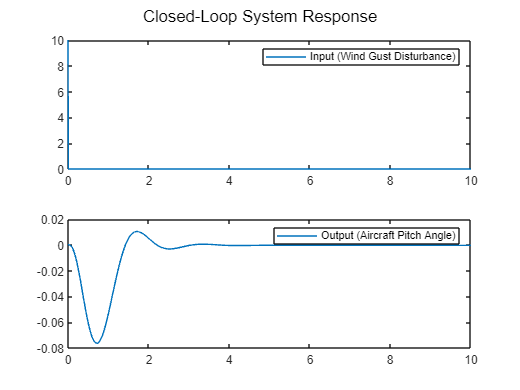


% Define the lumped (disturbance + control) input
t = 0:0.01:10;
w_amplitude = [10; 0; 0];
w_duration = 0.01;
w_impulse = w_amplitude * (t >= 0 & t < w_duration);
w = w_impulse;

% Simulate the open-loop system response
[y_cl, t_out, x_cl] = lsim(Scl, w', t);

% Plot the results
figure;
sgtitle('Closed-Loop System Response');
subplot(2, 1, 1);
plot(t, w(1, :));
legend('Input (Wind Gust Disturbance)');
subplot(2, 1, 2);
plot(t, y_cl(:, 1));
legend('Output (Aircraft Pitch Angle)');